# edited newmesh

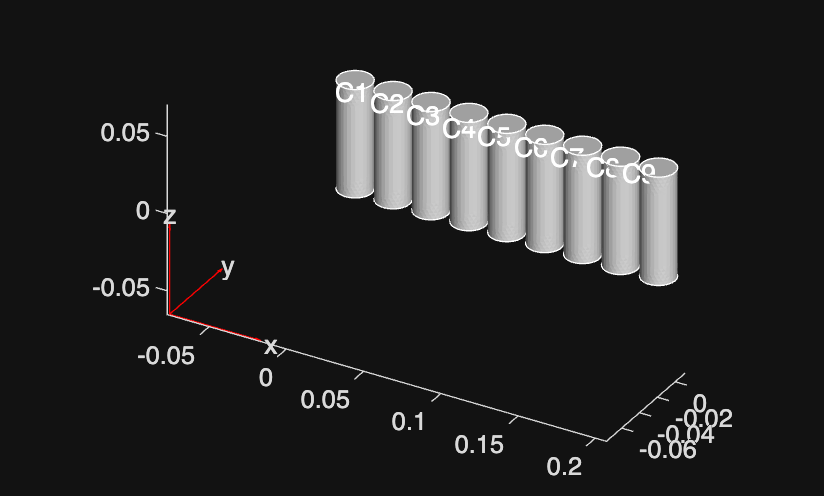

% dimensions
D=0.02155;
r=D/2;
h=0.070155;
m=0.07;
V=pi*r^2*h;
SA=2*pi*(r^2)+2*pi*(r^2)*h;
rho = m/V;          % density

% specs
V_nominal=3.6;
R_i=0.015;

% test conditions
I=10;               %c hoose a discharge current, A
T_ambient=25+273.15;
T_0=T_ambient;
h_conv = 20;         % can change to ftn later
% h_min = 10;
% h_max = 30;
  
% thermo
C_p=1040;   % specific heat, J/kg*K (???)
k_r=0.9;  %thermal conductivity (???)
k_theta=k_r;    %angle symmetry
k_z=24.2;    % (???)
q=(I^2)*(R_i)/V; %volumetric heat generation, W/m^3
    % for heat gen, can use a single constant value like q or a function (use
    % function handle when calling internalheatsource e.g. heatgen = @(region,
    % state))

% number and position of cylinders
N = 9;
sep = D+0.003;       
xpos = (0:N-1) * sep;

%  create mesh for one cylinder
baseModel = createpde();
baseGM = multicylinder(r, h);       
baseModel.Geometry = baseGM;
msh = generateMesh(baseModel,'Hmax',0.0025);  

% extract nodes and elems
nodes0 = msh.Nodes;           
elems0 = msh.Elements;        

allNodes = [];
allElems = [];
allElemsRegions = [];
nodeOffset = 0;


% copy cylinder N times
for k = 1:N
    % translate nodes in x
    nodesK = nodes0;
    nodesK(1,:) = nodesK(1,:) + xpos(k);

    % append nodes 
    allNodes = [allNodes, nodesK];

    % append elements with  offset
    elemsK = elems0 + nodeOffset;
    allElems = [allElems, elemsK];

    %need the number of elements in each region (cell) for elementid to
    %regionid in internal heat source call
    %say k is each cell
    elemspercell = size(elemsK, 2); % 2 is elements, 1 is nodes
    allElemsRegions = [allElemsRegions, k * ones(1, elemspercell)]; %now these elements are called k (1,2,...,N)

    nodeOffset = nodeOffset + size(nodesK,2);
end


% new PDE model from merged mesh
thermalmodel = createpde('thermal','transient');

% geometryFromMesh 
geometryFromMesh(thermalmodel,allNodes, allElems, allElemsRegions);
pdegplot(thermalmodel, "CellLabels","on")



% define heat generation ftn (if want to use instead of q)
% ex. heatgen = @(region, state) region.y .* region.x;


% define faces
allIDs = 1:thermalmodel.Geometry.NumFaces;   % all faces
locName = 'Face';

% define thermal properties + heat source
thermalProperties(thermalmodel, 'ThermalConductivity',k,'MassDensity',rho,'SpecificHeat',C_p);

for i=1:N
internalHeatSource(thermalmodel,q,"Cell",i);
end

% define boundary/initial conditions
thermalBC(thermalmodel,locName,allIDs,"ConvectionCoefficient",h_conv, "AmbientTemperature",T_ambient);
    % don't use T_ambient if using HeatFlux bc it's included in q_flux (HeatFlux) eq already
thermalIC(thermalmodel,T_0);    


% need to make h_conv functions local -- need to define local center (not
% global) for each cell
    %%%

% then need to edit this ftn to make it local instead of global
    % function q_flux = h_flux(region, state, T_ambient, h_min, h_max)
    %    T_local = state.u.';
    %    theta = atan2(region.x - xpos(k), region.y);
    %    h_conv = h_min + (h_max - h_min).*((1+cos(theta))/2);   %.* means element-wise multiplication
    %    q_flux = (h_conv * (T_local - T_ambient)).';
    % end

% solve
tlist = 0:5:3600; % time vector
result = solve(thermalmodel, tlist);
T_f=result.Temperature(:,end);

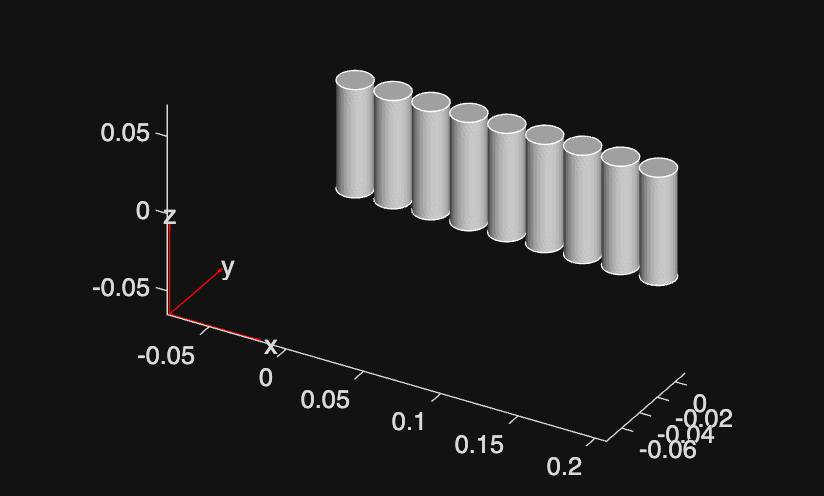

% visualize
pdegplot(thermalmodel.Geometry); axis equal         

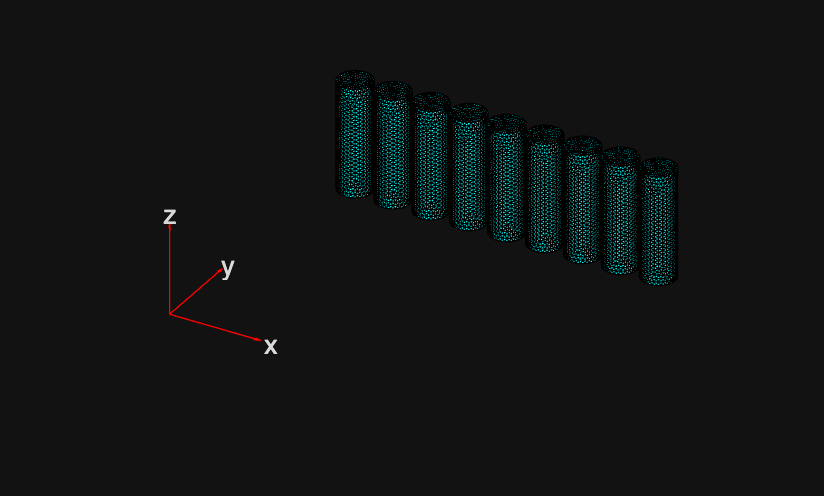

pdemesh(thermalmodel)

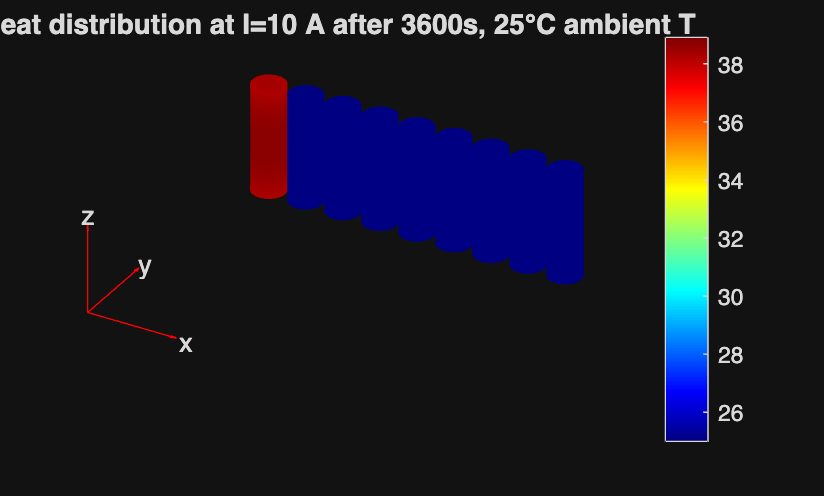

figure;
pdeplot3D(thermalmodel,"ColorMapData",T_f-273.15)
title(sprintf("Heat distribution at I=10 A after 3600s, 25°C ambient T"))
colorbar;

% note

